**3. Considere duas variáveis aleatórias relativas às classificações de uma turma de 120 alunos em duas Unidades Curriculares (ex: MPEI e POO). Designemos essas variáveis discretas por N1 e N2.**

**(a)** Gere N1 e N2 para que, antes de arredondamento para o valor inteiro mais próximo, tenham uma distribuição Normal com as seguintes médias e variâncias: média de N1 igual a 14; média de N2 20% superior a N1; variâncias iguais a 1/4 da média.

N1_media = 14;
N1_var = N1_media / 4;
N1_desvio = sqrt(N1_var);

N2_media = 1.2 * N1_media;
N2_var = N2_media / 4;
N2_desvio = sqrt(N2_var);

N1 = round(normrnd(N1_media, N1_desvio, 1, 120))

N1 =     14    13    14    15    16    14    15    14    14    15    13    15    15    14    17    13    13    11    16    16    14    16    14    15    14    15    14    19    12    11    12    12    13    14    14    15    15    15    17    16    12    10    16    11    14    14    18    14    13    14


N2 = round(normrnd(N2_media, N2_desvio, 1, 120))

N2 =     18    20    17    17    20    16    17    19    17    20    19    17    15    18    14    17    18    17    19    21    19    17    18    18    14    16    19    17    18    15    17    18    14    18    16    15    17    13    12    14    15    14    13    17    14    17    18    17    17    16


**(b)** Obtenha e represente graficamente a função probabilidade de massa conjunta de N1 e N2.

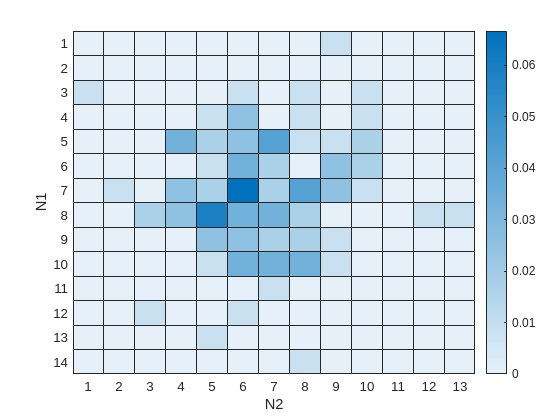

dist_junta = histcounts2(N1, N2, 'Normalization', 'probability');

heatmap(dist_junta, 'XLabel', 'N2', 'YLabel', 'N1');

**(c)** Qual o valor do coeficiente de correlação entre N1 e N2 ?

cov = sum(N1.*N2)/120

cov = 236.1000

coef_corr = cov/(N1_desvio * N2_desvio)

coef_corr = 61.5797

**(d)** N1 e N2 são independentes ?